## corrcoef() 的使用

按列做correlation coefficient

x = randn(6,1);
y = randn(6,1);
A = [x y 2*y+3]

A =    -0.8236    1.1275    5.2550
   -1.5771    0.3502    3.7004
    0.5080   -0.2991    2.4019
    0.2820    0.0229    3.0458
    0.0335   -0.2620    2.4760
   -1.3337   -1.7502   -0.5004


%% 由于2,3列线性相关,所以关联系数为1
corrcoef(A)

ans =     1.0000    0.0732    0.0732
    0.0732    1.0000    1.0000
    0.0732    1.0000    1.0000


load('data&fit_data.mat')

将用薄板插值得到的phase 和 rssi 拼接成一个大的向量

现在求的是,不同距离下的correlation coefficient

然后求corrcoef

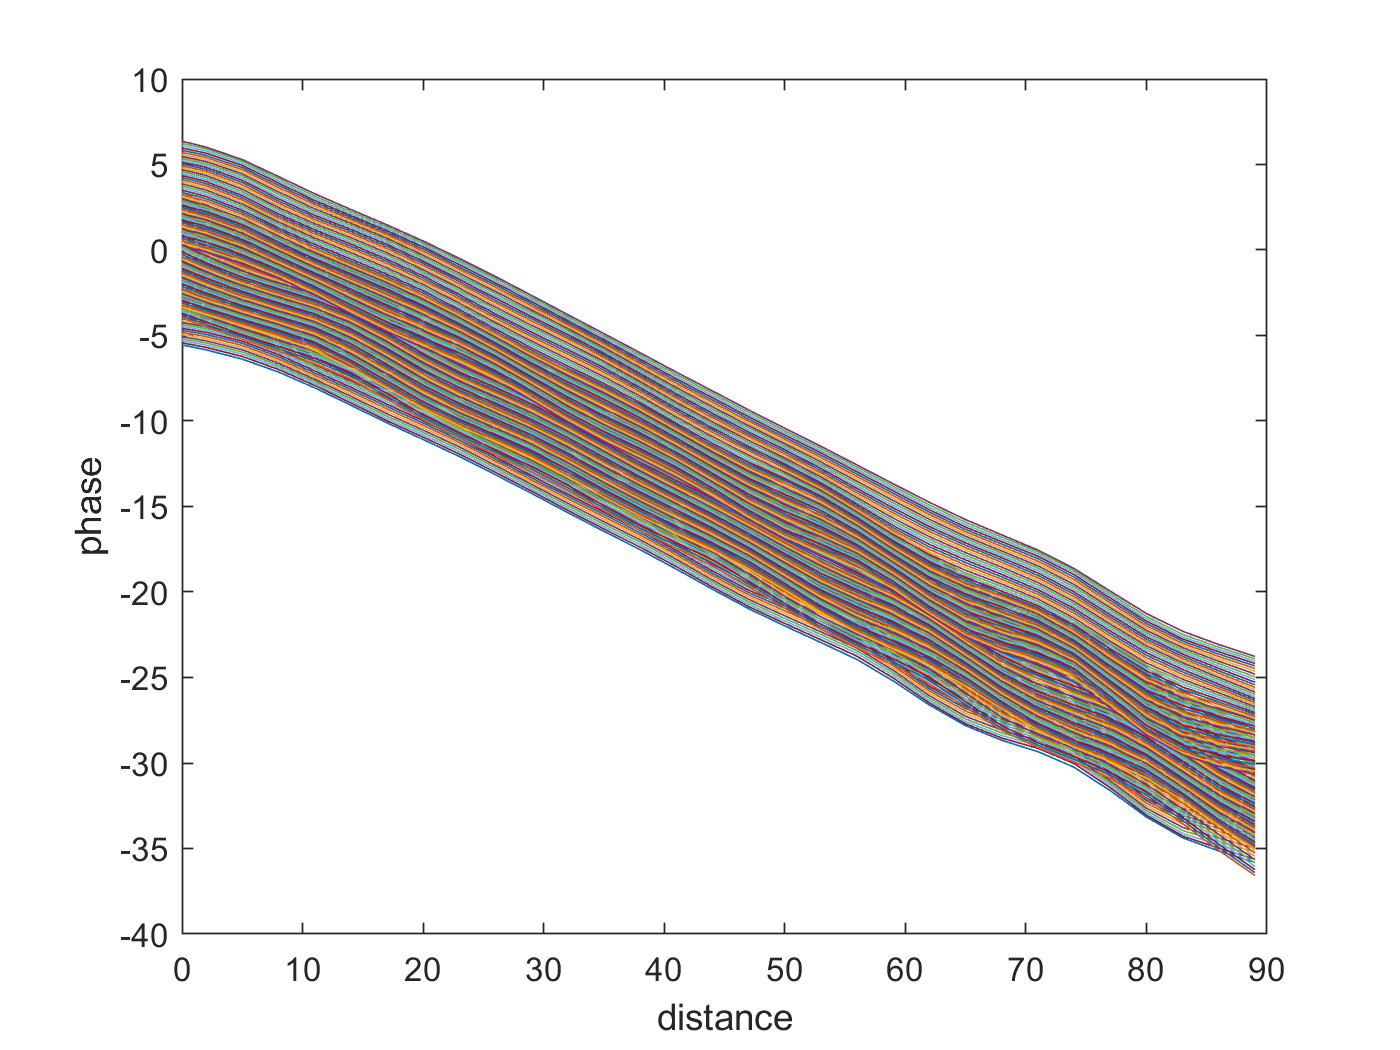

fitdata_phase_all=[fitdata_phase_e_90;fitdata_phase_w_90;...
    fitdata_phase_v_90;fitdata_phase_o_90;];
fitdata_rssi_all=[fitdata_rssi_e_90;fitdata_rssi_w_90;...
    fitdata_rssi_v_90;fitdata_rssi_o_90];
corrcoef_phase=corrcoef(fitdata_phase_all);
corrcoef_rssi=corrcoef(fitdata_rssi_all);
%%
plot(distance_list,fitdata_phase_all')
xlabel('distance')
ylabel('phase')

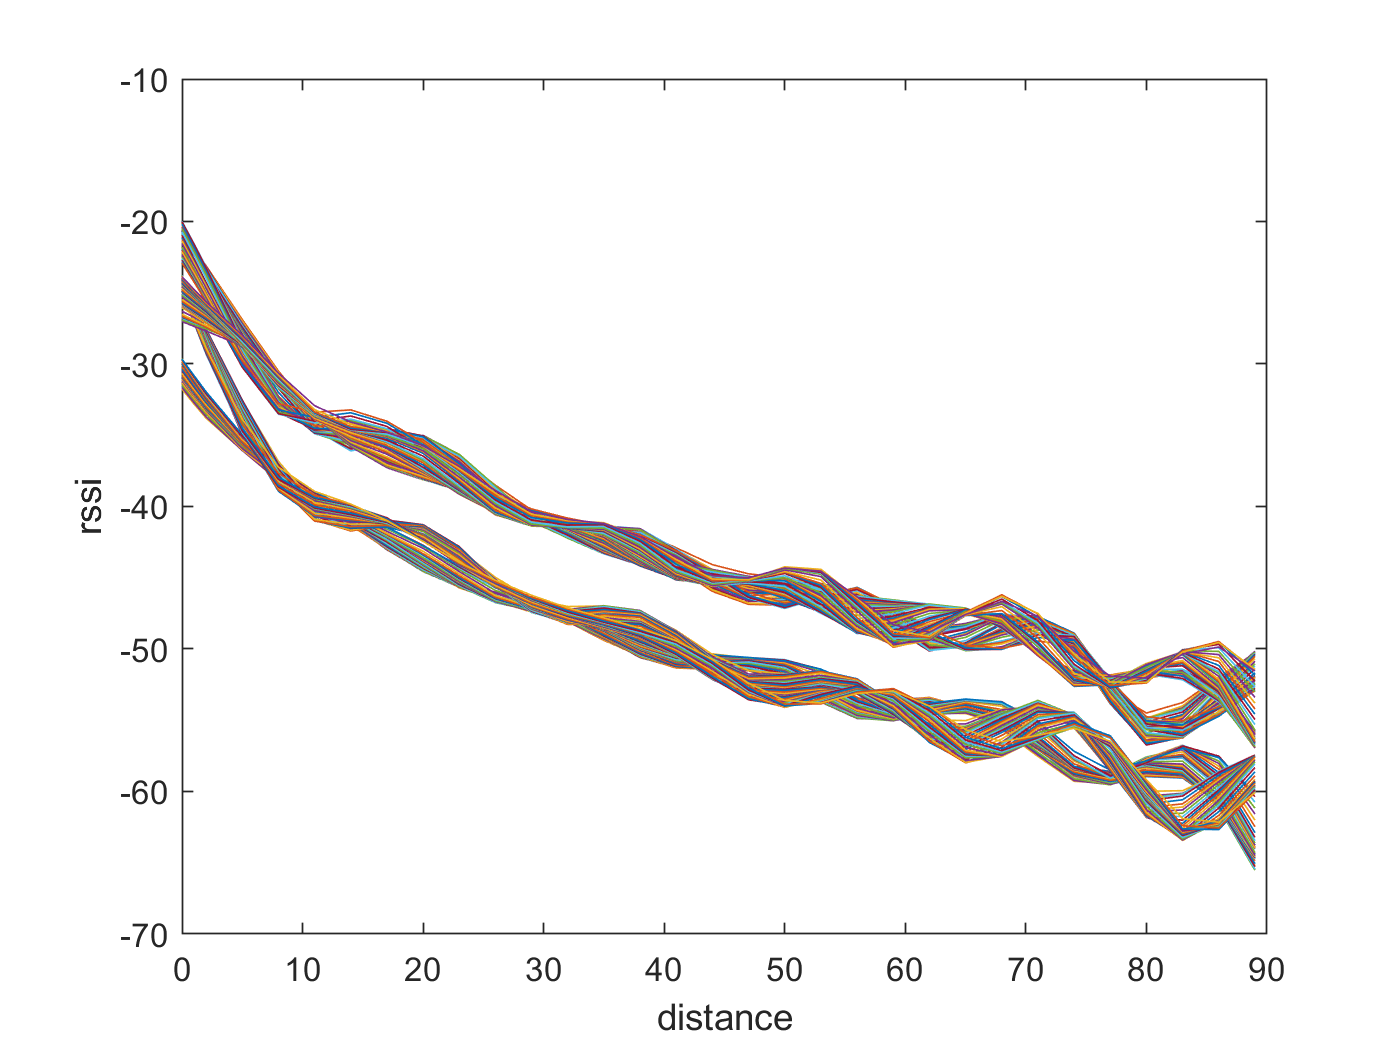


plot(distance_list,fitdata_rssi_all')
xlabel('distance')
ylabel('rssi')

按照以上数据得到的correlation coefficient

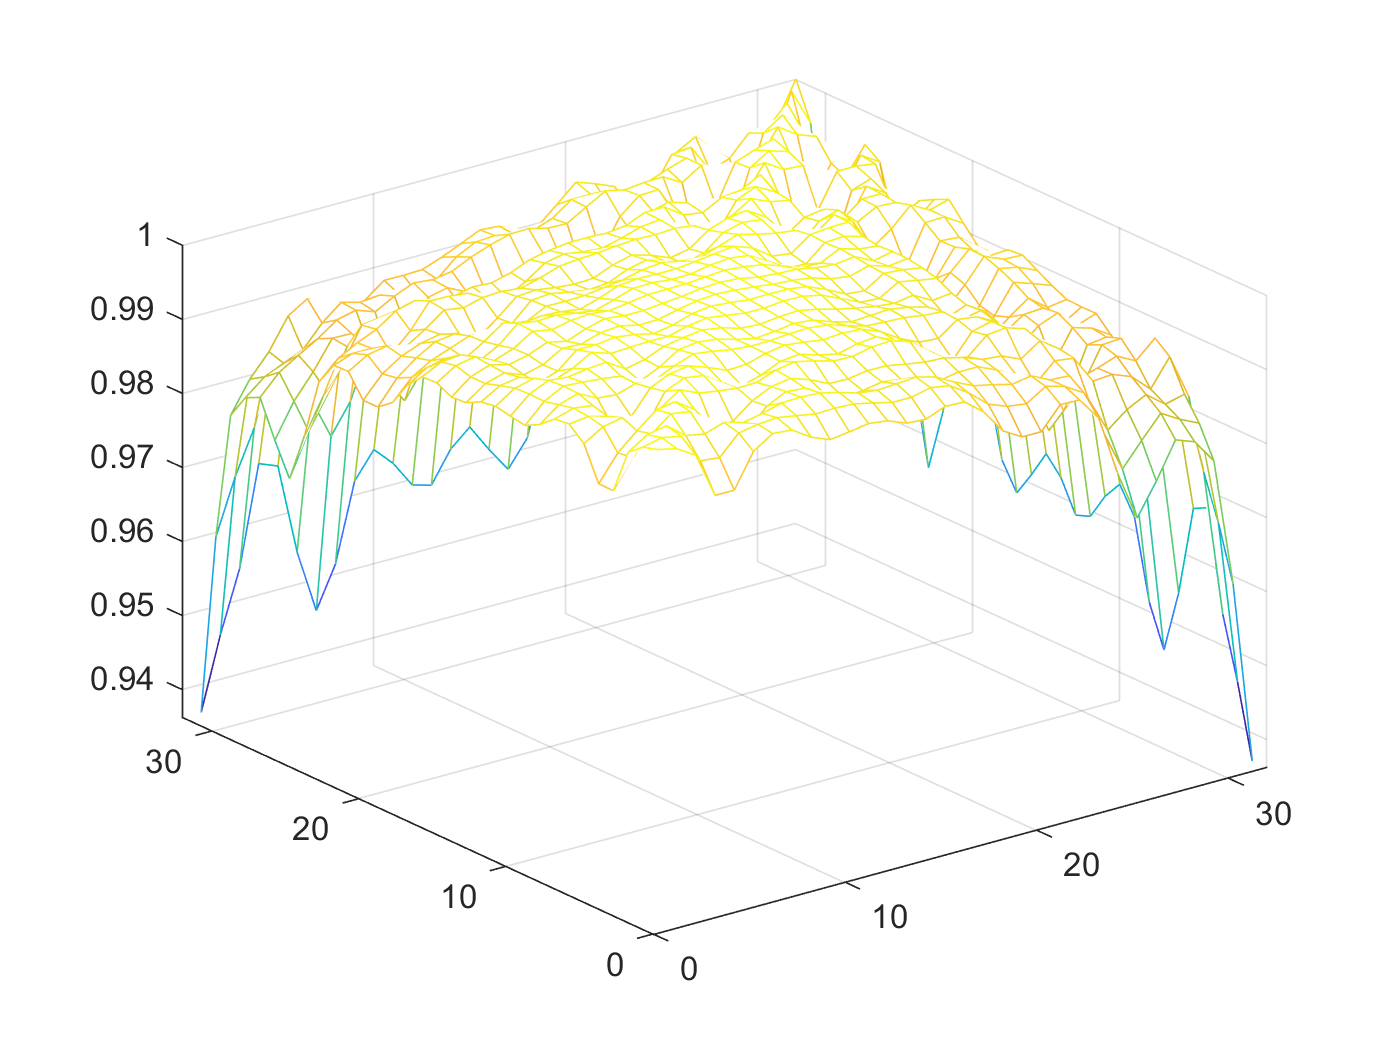

mesh(corrcoef_phase)

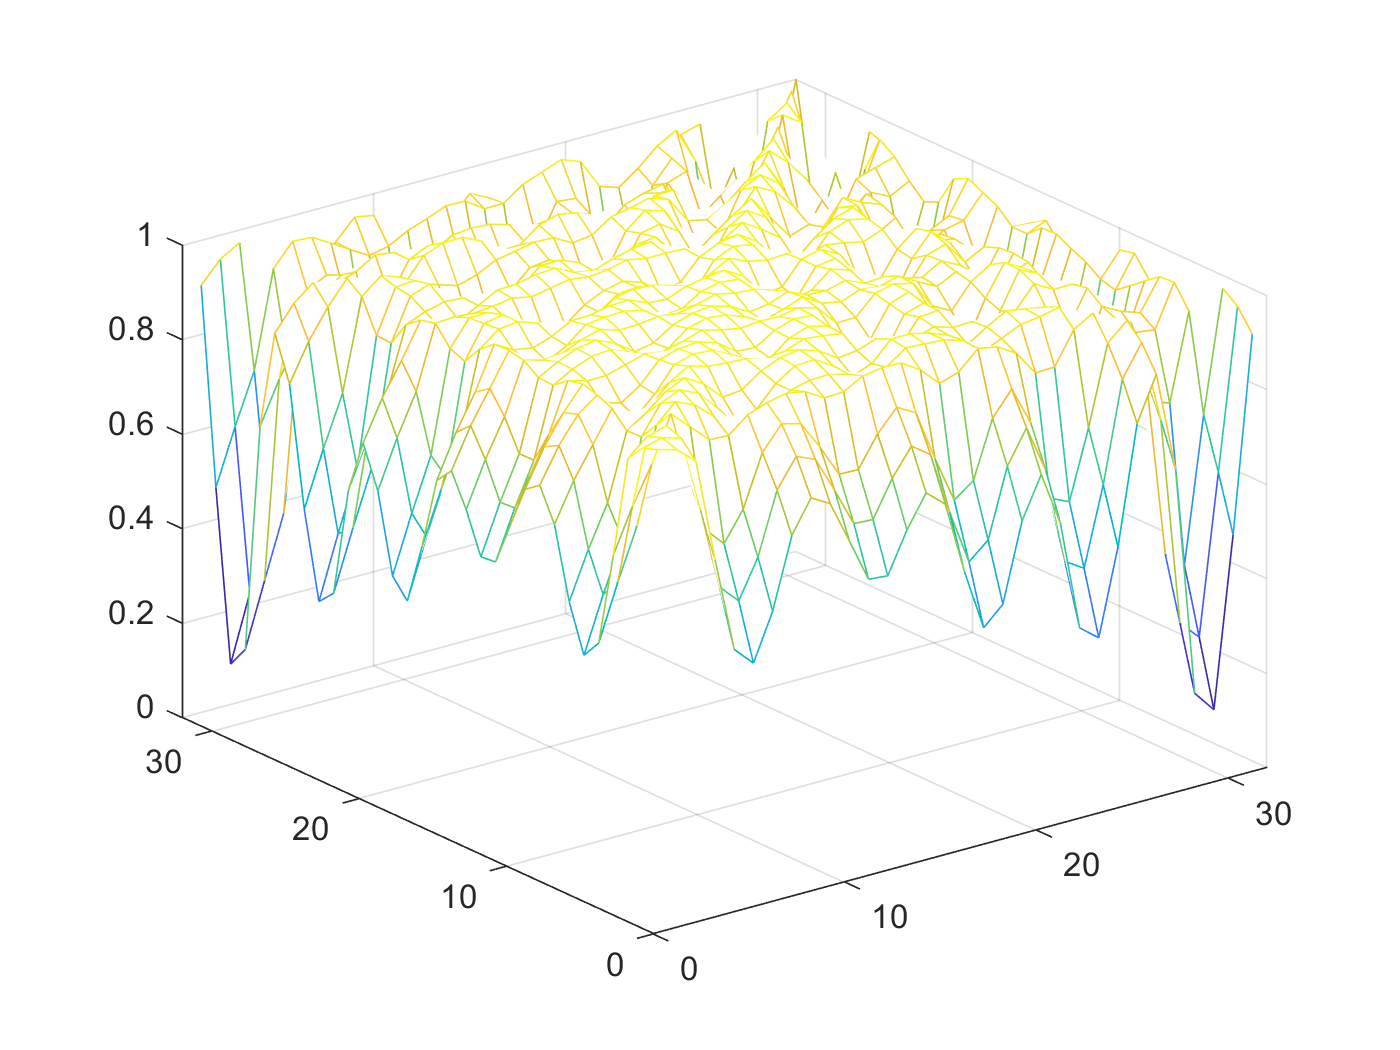

mesh(corrcoef_rssi)

直接求三组数据之间的correlation coefficient

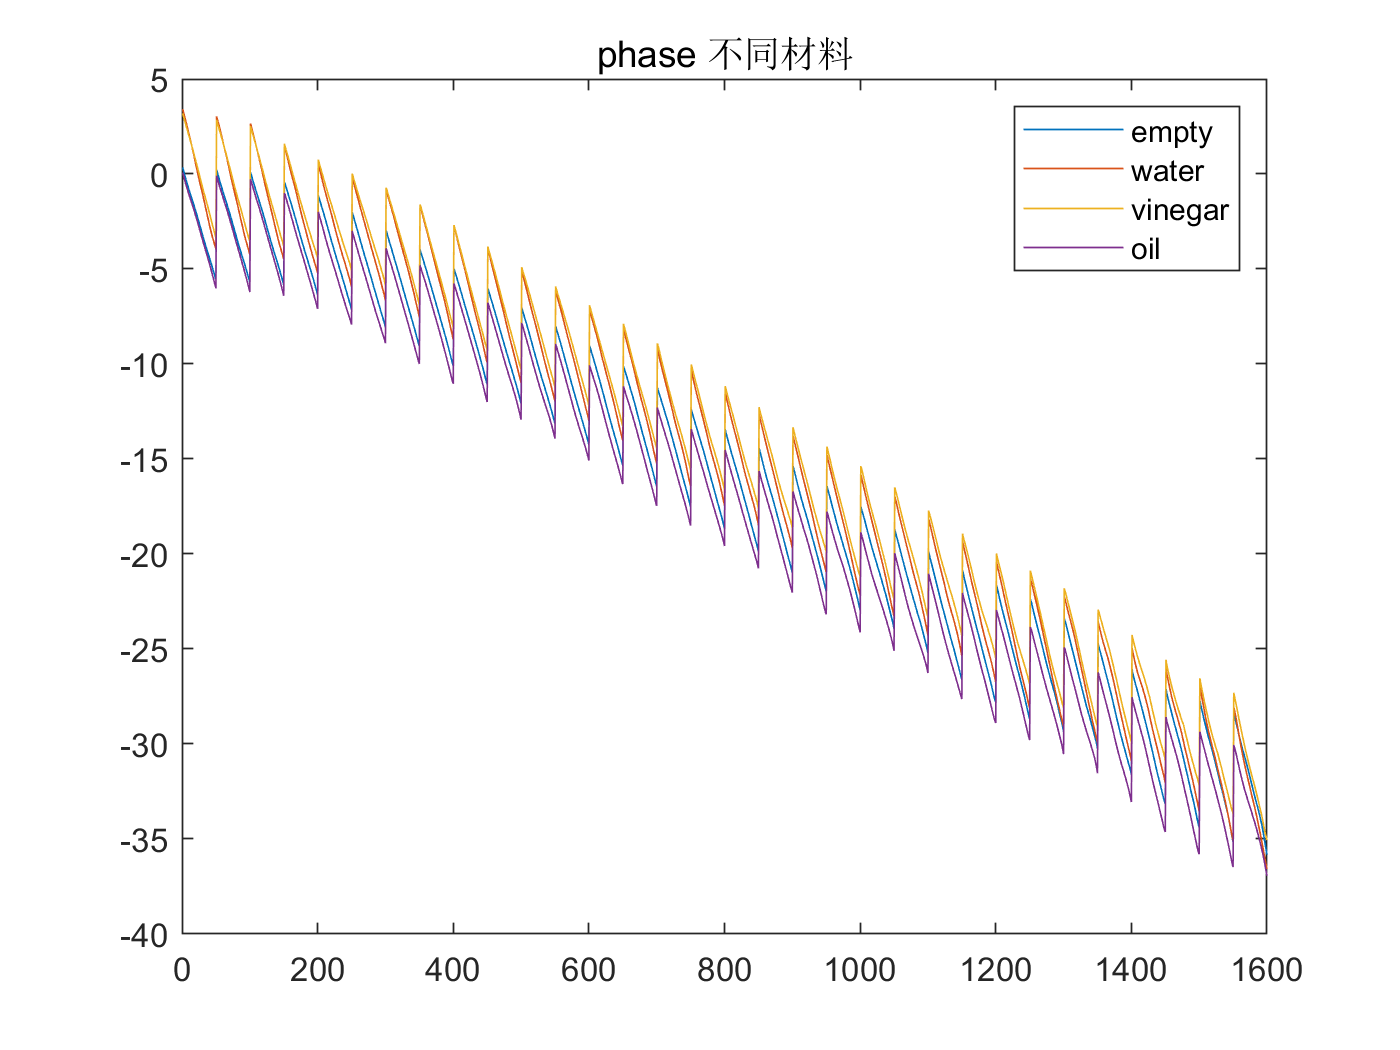

fitdata_phase_all1=[fitdata_phase_e_90(:),fitdata_phase_w_90(:),...
    fitdata_phase_v_90(:),fitdata_phase_o_90(:)-2*pi];
fitdata_rssi_all1=[fitdata_rssi_e_90(:),fitdata_rssi_w_90(:),...
    fitdata_rssi_v_90(:),fitdata_rssi_o_90(:)];

plot(fitdata_phase_all1)
title('phase 不同材料')
legend('empty','water','vinegar','oil')

corrcoef_phase=corrcoef(fitdata_phase_all1)

corrcoef_phase =     1.0000    0.9993    0.9994    0.9999
    0.9993    1.0000    0.9998    0.9992
    0.9994    0.9998    1.0000    0.9994
    0.9999    0.9992    0.9994    1.0000


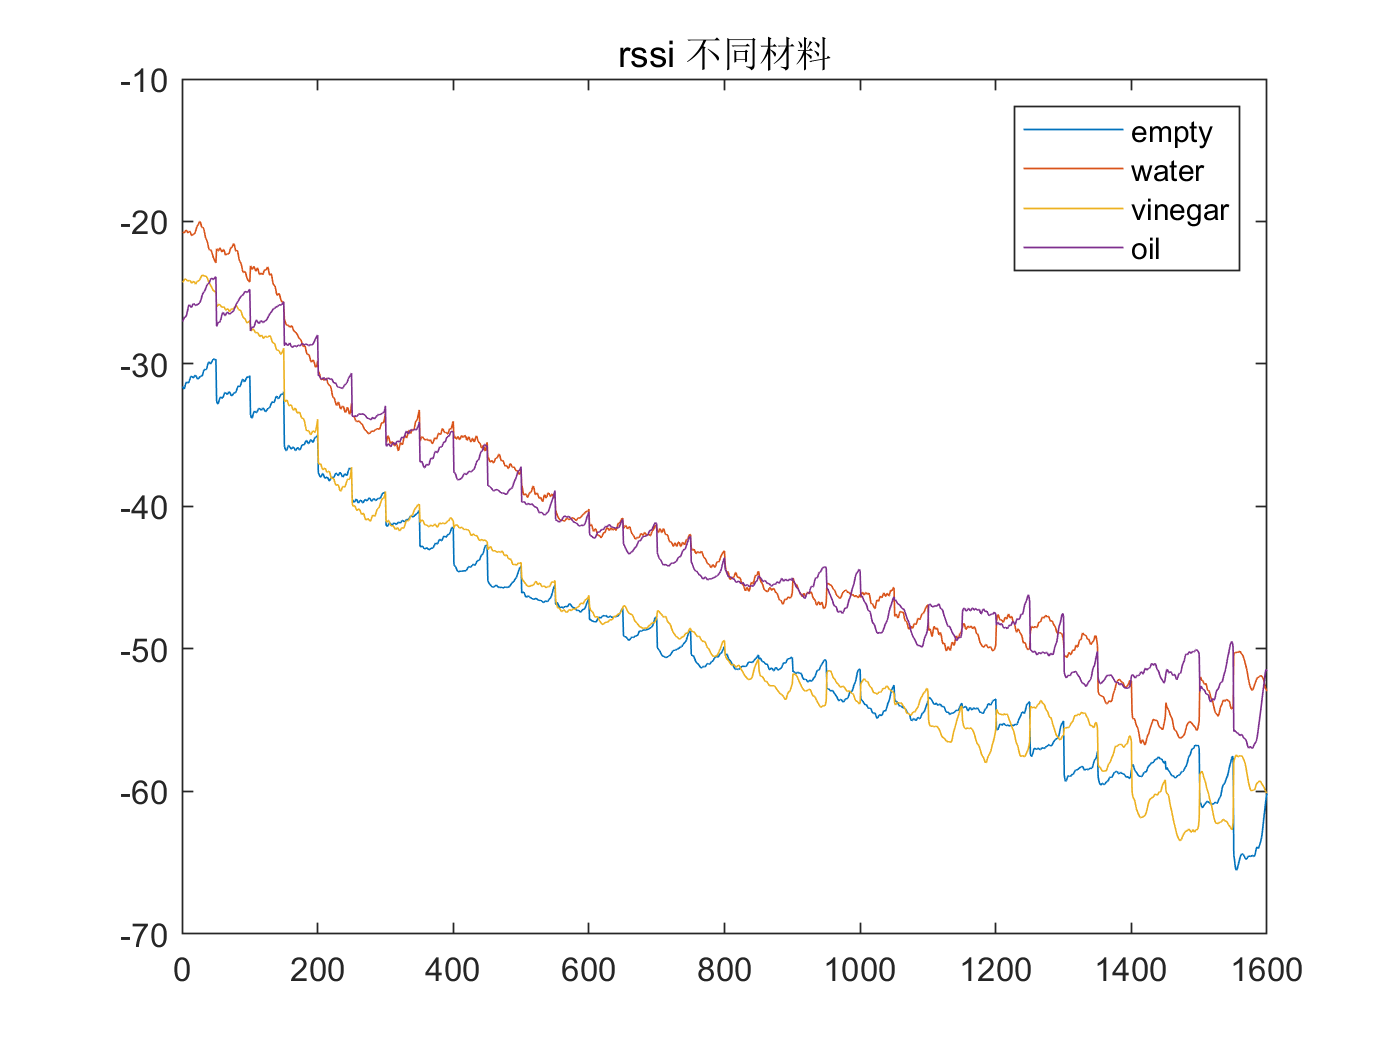



plot(fitdata_rssi_all1)
title('rssi 不同材料')
legend('empty','water','vinegar','oil')

corrcoef_rssi=corrcoef(fitdata_rssi_all1)

corrcoef_rssi =     1.0000    0.9744    0.9714    0.9970
    0.9744    1.0000    0.9960    0.9759
    0.9714    0.9960    1.0000    0.9709
    0.9970    0.9759    0.9709    1.0000
